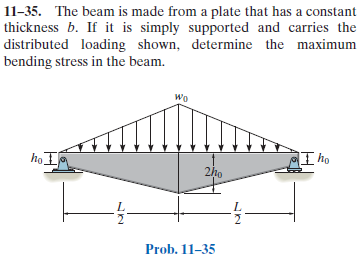

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-35P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-35P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

wo = sym('wo', 'positive');
L = sym('L', 'positive');
w1 = findpoly(1, 'thru', [0 0], [L/2 -wo]);
w2 = findpoly(1, 'thru', [L/2 -wo], [L 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'R1', 0);
b = b.add('reaction', 'force', 'R2', L);
b = b.add('distributed', 'force', w1, [0 L/2]);
b = b.add('distributed', 'force', w2, [L/2 L], [false true]);

# section properties

x = sym('x');
B = sym('B', 'positive');
Ho = sym('Ho', 'positive');

H1 = findpoly(1, 'thru', [0 Ho], [L/2 2*Ho]);
H2 = findpoly(1, 'thru', [L/2 2*Ho], [L Ho]);
H = piecewise(x <= L/2,  H1, x > L/2, H2);
b.I = B*H^3/12;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{L^{2}\,\mathrm{wo}\,\left(22\,L\,x^{2}+5\,L^{2}\,x+6\,L^{3}\,\log\left(L\right)+8\,x^{3}-6\,L^{3}\,\log\left(L+2\,x\right)-12\,L\,x^{2}\,\log\left(L\right)+6\,L^{2}\,x\,\log\left(L\right)-24\,L\,x^{2}\,\log\left(L+2\,x\right)-24\,L^{2}\,x\,\log\left(L+2\,x\right)-60\,L\,x^{2}\,\log\left(-L\right)-30\,L^{2}\,x\,\log\left(-L\right)+24\,L\,x^{2}\,\log\left(-2\,L\right)+36\,L\,x^{2}\,\log\left(2\,L\right)+12\,L^{2}\,x\,\log\left(-2\,L\right)+18\,L^{2}\,x\,\log\left(2\,L\right)+36\,L\,x^{2}\,\log\left(-\frac{L}{2}\right)+18\,L^{2}\,x\,\log\left(-\frac{L}{2}\right)\right)}{16\,B\,\text{E}\,{\mathrm{Ho}}^{3}\,\left(L+2\,x\right)} & \text{ if }2\,x\leq L\\ \frac{L^{2}\,\mathrm{wo}\,\left(54\,L^{3}\,\log\left(\frac{3\,L}{2}-x\right)-54\,L^{3}\,\log\left(-L\right)+3\,L^{3}\,\log\left(64\right)-46\,L\,x^{2}+73\,L^{2}\,x-35\,L^{3}+8\,x^{3}-60\,L\,x^{2}\,\log\left(-L\right)+126\,L^{2}\,x\,\log\left(-L\right)+36\,L\,x^{2}\,\log\left(-\frac{L}{2}\right)-54\,L^{2}\,x\,\log\left(-\frac{L}{2}\right)+24\,L\,x^{2}\,\log\left(3\,L-2\,x\right)-36\,L^{2}\,x\,\log\left(3\,L-2\,x\right)-36\,L^{2}\,x\,\log\left(\frac{3\,L}{2}-x\right)+2\,L\,x^{2}\,\log\left(64\right)-5\,L^{2}\,x\,\log\left(64\right)+54\,\pi \,L^{3}\,\mathrm{i}+24\,\pi \,L\,x^{2}\,\mathrm{i}-72\,\pi \,L^{2}\,x\,\mathrm{i}\right)}{16\,B\,\text{E}\,{\mathrm{Ho}}^{3}\,\left(3\,L-2\,x\right)} & \text{ if }L<2\,x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{L^{2}\,\mathrm{wo}\,\left(12\,L^{3}\,\log\left(-2\,L\right)-30\,L^{3}\,\log\left(-L\right)+18\,L^{3}\,\log\left(-\frac{L}{2}\right)+18\,L^{3}\,\log\left(2\right)+20\,L\,x^{2}-4\,L^{2}\,x-7\,L^{3}+12\,L^{3}\,\log\left(L\right)+32\,x^{3}-12\,L^{3}\,\log\left(L+2\,x\right)+48\,L\,x^{2}\,\log\left(L\right)+48\,L^{2}\,x\,\log\left(L\right)-48\,L\,x^{2}\,\log\left(L+2\,x\right)-48\,L^{2}\,x\,\log\left(L+2\,x\right)-120\,L\,x^{2}\,\log\left(-L\right)-120\,L^{2}\,x\,\log\left(-L\right)+48\,L\,x^{2}\,\log\left(-2\,L\right)+48\,L^{2}\,x\,\log\left(-2\,L\right)+72\,L\,x^{2}\,\log\left(-\frac{L}{2}\right)+72\,L^{2}\,x\,\log\left(-\frac{L}{2}\right)+72\,L\,x^{2}\,\log\left(2\right)+72\,L^{2}\,x\,\log\left(2\right)\right)}{16\,B\,\text{E}\,{\mathrm{Ho}}^{3}\,{\left(L+2\,x\right)}^{2}} & \text{ if }2\,x\leq L\\ -\frac{L^{2}\,\mathrm{wo}\,\left(162\,L^{3}\,\log\left(-\frac{L}{2}\right)-270\,L^{3}\,\log\left(-L\right)+108\,L^{3}\,\log\left(3\,L-2\,x\right)+9\,L^{3}\,\log\left(64\right)-116\,L\,x^{2}+132\,L^{2}\,x-41\,L^{3}+32\,x^{3}-120\,L\,x^{2}\,\log\left(-L\right)+360\,L^{2}\,x\,\log\left(-L\right)+72\,L\,x^{2}\,\log\left(-\frac{L}{2}\right)-216\,L^{2}\,x\,\log\left(-\frac{L}{2}\right)+48\,L\,x^{2}\,\log\left(3\,L-2\,x\right)-144\,L^{2}\,x\,\log\left(3\,L-2\,x\right)+4\,L\,x^{2}\,\log\left(64\right)-12\,L^{2}\,x\,\log\left(64\right)+108\,\pi \,L^{3}\,\mathrm{i}+48\,\pi \,L\,x^{2}\,\mathrm{i}-144\,\pi \,L^{2}\,x\,\mathrm{i}\right)}{16\,B\,\text{E}\,{\mathrm{Ho}}^{3}\,{\left(3\,L-2\,x\right)}^{2}} & \text{ if }L<2\,x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,x\,\left(3\,L^{2}-4\,x^{2}\right)}{12\,L} & \text{ if }2\,x\leq L\\ -\frac{\mathrm{wo}\,\left(L-x\right)\,\left(L^{2}-8\,L\,x+4\,x^{2}\right)}{12\,L} & \text{ if }L<2\,x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,\left(L-2\,x\right)\,\left(L+2\,x\right)}{4\,L} & \text{ if }2\,x\leq L\\ \frac{\mathrm{wo}\,\left(L-2\,x\right)\,\left(3\,L-2\,x\right)}{4\,L} & \text{ if }L<2\,x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{2\,\mathrm{wo}\,x}{L} & \text{ if }2\,x\leq L\\ -\frac{2\,\mathrm{wo}\,\left(L-x\right)}{L} & \text{ if }L<2\,x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} R_{1} & \frac{L\,\mathrm{wo}}{4}\\ R_{2} & \frac{L\,\mathrm{wo}}{4} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

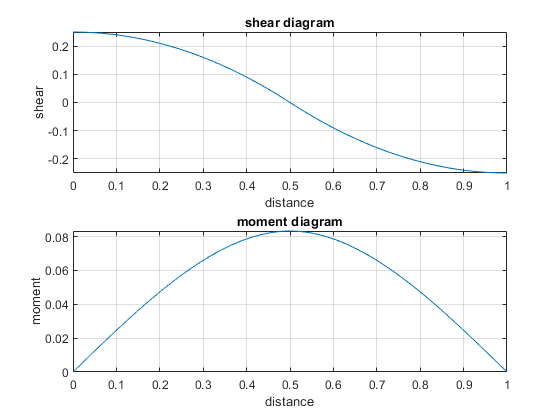

beam.shear_moment(m, v, [0 1], [wo L], 1);

# bending stress formula

C = H/2;
sigma = -m*C/b.I

$$sigma(x) = \left\{ \begin{array}{cl} -\frac{L\,\mathrm{wo}\,x\,\left(3\,L^{2}-4\,x^{2}\right)}{2\,B\,{\mathrm{Ho}}^{2}\,{\left(L+2\,x\right)}^{2}} & \text{ if }2\,x\leq L\\ \frac{L\,\mathrm{wo}\,\left(L-x\right)\,\left(L^{2}-8\,L\,x+4\,x^{2}\right)}{2\,B\,{\mathrm{Ho}}^{2}\,{\left(3\,L-2\,x\right)}^{2}} & \text{ if }L<2\,x \end{array}\right.$$

# maximum bending stress

assumeAlso(0 <= x & x <= b.L);
soln = solve(diff(sigma) == 0, 'MaxDegree', 3, 'ReturnConditions', true);
x_max(L) = simplify(soln.x(1))

$$x\_max(L) = \frac{L\,\left(2^{2/3}-1\right)}{2}$$

sigma_max(wo, L, B, Ho) = simplify(sigma(x_max))

$$sigma\_max(wo, L, B, Ho) = \frac{3\,L^{2}\,\mathrm{wo}\,\left(2^{2/3}-2\right)}{8\,B\,{\mathrm{Ho}}^{2}}$$

# clean up

clearassum(x);
new_assum = assumptions;
clear soln;